Complete Training, Validation, and Comparison Pipeline

%% PINN Training, Validation, and Ground-Truth Comparison Pipeline
clear; clc; close all; rng(42);

% --- 1. Load Preprocessed DeepCFD Data ---
dataFile = fullfile(pwd, 'DeepCFD_preprocessed.mat');
if ~exist(dataFile, 'file')
    error('Could not find DeepCFD_preprocessed.mat. Run the preprocessing script first.');
end
load(dataFile, 'X_train', 'Y_train', 'X_val', 'Y_val', 'normStats');

% Extract representative sample (Index 1) for point-wise PINN evaluation
% Domain coordinates from grid: Height (Ny), Width (Nx)
[Ny, Nx, ~, ~] = size(X_train);
x_lin = linspace(0.0, 2.0, Nx);
y_lin = linspace(-0.5, 0.5, Ny);
[X_grid, Y_grid] = meshgrid(x_lin, y_lin);

% Ground-truth normalized fields for target sample
Ux_true = squeeze(Y_train(:, :, 1, 1));
Uy_true = squeeze(Y_train(:, :, 2, 1));
P_true  = squeeze(Y_train(:, :, 3, 1));

% Collocation points across domain
x_colloc = single(X_grid(:));
y_colloc = single(Y_grid(:));
pts_dl   = dlarray([x_colloc'; y_colloc'], 'CB');

% Training targets as dlarray
targets_dl = dlarray([Ux_true(:)'; Uy_true(:)'; P_true(:)'], 'CB');

% Validation slice targets
Ux_val_true = squeeze(Y_val(:, :, 1, 1));
Uy_val_true = squeeze(Y_val(:, :, 2, 1));
P_val_true  = squeeze(Y_val(:, :, 3, 1));
targets_val_dl = dlarray([Ux_val_true(:)'; Uy_val_true(:)'; P_val_true(:)'], 'CB');

% --- 2. Neural Network Architecture ---
layers = [
    featureInputLayer(2, 'Name', 'coords_in')
    fullyConnectedLayer(64, 'Name', 'fc1')
    tanhLayer('Name', 'act1')
    fullyConnectedLayer(64, 'Name', 'fc2')
    tanhLayer('Name', 'act2')
    fullyConnectedLayer(64, 'Name', 'fc3')
    tanhLayer('Name', 'act3')
    fullyConnectedLayer(64, 'Name', 'fc4')
    tanhLayer('Name', 'act4')
    fullyConnectedLayer(3, 'Name', 'state_out')
];
net = dlnetwork(layers);

% --- 3. Training Hyperparameters ---
numEpochs    = 1500;
learnRate    = 1e-3;
nu           = single(0.01);
w_data       = single(10.0);
w_pde        = single(1.0);

averageGrad   = [];
averageSqGrad = [];

valHistory   = zeros(ceil(numEpochs/50), 2);
valIdx       = 1;

fprintf('Beginning combined Data + Navier-Stokes PINN Training...\n');

Beginning combined Data + Navier-Stokes PINN Training...



% --- 4. Main Optimization Loop ---
for epoch = 1:numEpochs
    % Compute loss, gradients, and residuals
    [loss, grads, l_data, l_pde] = dlfeval(@computePINNLoss, ...
        net, pts_dl, targets_dl, nu, w_data, w_pde);
    
    % Update weights using Adam
    [net, averageGrad, averageSqGrad] = adamupdate(net, grads, ...
        averageGrad, averageSqGrad, epoch, learnRate);
    
    % Validation and Progress Logging
    if mod(epoch, 50) == 0 || epoch == 1
        % Evaluate on validation targets
        pred_val = forward(net, pts_dl);
        val_l2_err = norm(extractdata(pred_val - targets_val_dl)) / norm(extractdata(targets_val_dl));
        
        valHistory(valIdx, :) = [epoch, val_l2_err];
        valIdx = valIdx + 1;
        
        fprintf('Epoch: %4d | Total Loss: %.4e | Data Loss: %.4e | PDE Residual: %.4e | Val Rel L2: %.4e\n', ...
            epoch, double(gather(extractdata(loss))), ...
            double(gather(extractdata(l_data))), ...
            double(gather(extractdata(l_pde))), val_l2_err);
    end
end

Epoch:    1 | Total Loss: 1.1426e+00 | Data Loss: 9.6686e-02 | PDE Residual: 1.7578e-01 | Val Rel L2: 5.3461e-01
Epoch:   50 | Total Loss: 3.7650e-02 | Data Loss: 3.5542e-03 | PDE Residual: 2.1082e-03 | Val Rel L2: 1.6639e-01
Epoch:  100 | Total Loss: 3.2665e-02 | Data Loss: 3.1724e-03 | PDE Residual: 9.4130e-04 | Val Rel L2: 1.6446e-01
Epoch:  150 | Total Loss: 3.1630e-02 | Data Loss: 3.0967e-03 | PDE Residual: 6.6298e-04 | Val Rel L2: 1.6394e-01
Epoch:  200 | Total Loss: 3.1082e-02 | Data Loss: 3.0529e-03 | PDE Residual: 5.5287e-04 | Val Rel L2: 1.6363e-01
Epoch:  250 | Total Loss: 3.0761e-02 | Data Loss: 3.0260e-03 | PDE Residual: 5.0129e-04 | Val Rel L2: 1.6339e-01
Epoch:  300 | Total Loss: 3.0562e-02 | Data Loss: 3.0088e-03 | PDE Residual: 4.7399e-04 | Val Rel L2: 1.6320e-01
Epoch:  350 | Total Loss: 3.0433e-02 | Data Loss: 2.9975e-03 | PDE Residual: 4.5820e-04 | Val Rel L2: 1.6303e-01
Epoch:  400 | Total Loss: 3.0345e-02 | Data Loss: 2.9896e-03 | PDE Residual: 4.4854e-04 | Val Re

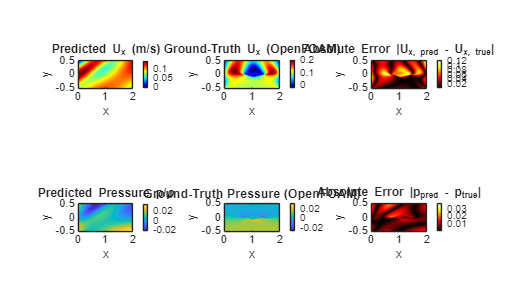


% --- 5. Validation and Error Field Visualization ---
pred_final = forward(net, pts_dl);
Ux_pred = reshape(extractdata(pred_final(1, :)), [Ny, Nx]);
Uy_pred = reshape(extractdata(pred_final(2, :)), [Ny, Nx]);
P_pred  = reshape(extractdata(pred_final(3, :)), [Ny, Nx]);

% Un-normalize to physical domain values
u_min = normStats.Y_min(1, 1, 1); u_max = normStats.Y_max(1, 1, 1);
p_min = normStats.Y_min(1, 1, 3); p_max = normStats.Y_max(1, 1, 3);

Ux_pred_phys = 0.5 * (Ux_pred + 1) * (u_max - u_min) + u_min;
Ux_true_phys = 0.5 * (Ux_val_true + 1) * (u_max - u_min) + u_min;
Ux_err = abs(Ux_pred_phys - Ux_true_phys);

P_pred_phys = 0.5 * (P_pred + 1) * (p_max - p_min) + p_min;
P_true_phys = 0.5 * (P_val_true + 1) * (p_max - p_min) + p_min;
P_err = abs(P_pred_phys - P_true_phys);

% Validation Comparison Plots (Predicted vs Ground-Truth vs Absolute Error)
figure('Position', [50, 50, 1300, 750], 'Color', 'w');

% Horizontal Velocity Comparison
subplot(2, 3, 1);
contourf(X_grid, Y_grid, Ux_pred_phys, 40, 'LineColor', 'none');
colorbar; colormap(gca, 'jet'); title('Predicted U_x (m/s)'); xlabel('x'); ylabel('y'); axis equal tight;

subplot(2, 3, 2);
contourf(X_grid, Y_grid, Ux_true_phys, 40, 'LineColor', 'none');
colorbar; colormap(gca, 'jet'); title('Ground-Truth U_x (OpenFOAM)'); xlabel('x'); ylabel('y'); axis equal tight;

subplot(2, 3, 3);
contourf(X_grid, Y_grid, Ux_err, 40, 'LineColor', 'none');
colorbar; colormap(gca, 'hot'); title('Absolute Error |U_{x, pred} - U_{x, true}|'); xlabel('x'); ylabel('y'); axis equal tight;

% Pressure Comparison
subplot(2, 3, 4);
contourf(X_grid, Y_grid, P_pred_phys, 40, 'LineColor', 'none');
colorbar; colormap(gca, 'parula'); title('Predicted Pressure p/\rho'); xlabel('x'); ylabel('y'); axis equal tight;

subplot(2, 3, 5);
contourf(X_grid, Y_grid, P_true_phys, 40, 'LineColor', 'none');
colorbar; colormap(gca, 'parula'); title('Ground-Truth Pressure (OpenFOAM)'); xlabel('x'); ylabel('y'); axis equal tight;

subplot(2, 3, 6);
contourf(X_grid, Y_grid, P_err, 40, 'LineColor', 'none');
colorbar; colormap(gca, 'hot'); title('Absolute Error |p_{pred} - p_{true}|'); xlabel('x'); ylabel('y'); axis equal tight;

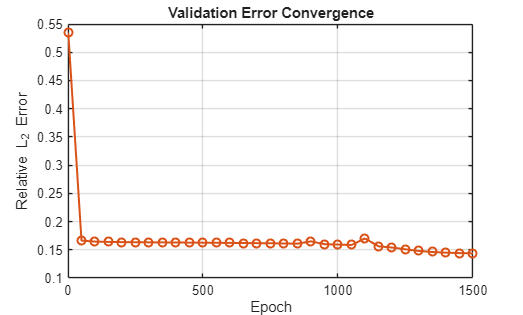


% Validation Error Convergence Plot
figure('Color', 'w');
plot(valHistory(:, 1), valHistory(:, 2), '-o', 'LineWidth', 1.5, 'Color', [0.85 0.325 0.098]);
xlabel('Epoch'); ylabel('Relative L_2 Error');
title('Validation Error Convergence'); grid on;

xlim([0 1500])
ylim([0.100 0.550])


%% --- Loss Evaluation Function ---
function [totalLoss, gradients, lossData, lossPDE] = computePINNLoss(net, ...
    pts, targets, nu, w_data, w_pde)

    x = pts(1, :);
    y = pts(2, :);
    
    % Forward pass
    pred = forward(net, [x; y]);
    u = pred(1, :);
    v = pred(2, :);
    p = pred(3, :);
    
    % Empirical Data Loss
    lossData = mean((pred - targets).^2, 'all');
    
    % Automatic Differentiation for Navier-Stokes residuals
    u_x = dlgradient(sum(u, 'all'), x, 'EnableHigherDerivatives', true);
    u_y = dlgradient(sum(u, 'all'), y, 'EnableHigherDerivatives', true);
    v_x = dlgradient(sum(v, 'all'), x, 'EnableHigherDerivatives', true);
    v_y = dlgradient(sum(v, 'all'), y, 'EnableHigherDerivatives', true);
    p_x = dlgradient(sum(p, 'all'), x, 'EnableHigherDerivatives', false);
    p_y = dlgradient(sum(p, 'all'), y, 'EnableHigherDerivatives', false);
    
    u_xx = dlgradient(sum(u_x, 'all'), x, 'EnableHigherDerivatives', false);
    u_yy = dlgradient(sum(u_y, 'all'), y, 'EnableHigherDerivatives', false);
    v_xx = dlgradient(sum(v_x, 'all'), x, 'EnableHigherDerivatives', false);
    v_yy = dlgradient(sum(v_y, 'all'), y, 'EnableHigherDerivatives', false);
    
    % Incompressible Navier-Stokes residuals
    res_cont = u_x + v_y;
    res_mom_x = (u .* u_x + v .* u_y) + p_x - nu .* (u_xx + u_yy);
    res_mom_y = (u .* v_x + v .* v_y) + p_y - nu .* (v_xx + v_yy);
    
    lossPDE = mean(res_cont.^2, 'all') + ...
              mean(res_mom_x.^2, 'all') + ...
              mean(res_mom_y.^2, 'all');
          
    totalLoss = (w_data * lossData) + (w_pde * lossPDE);
    gradients = dlgradient(totalLoss, net.Learnables);
end


  Save `PINN_Trained_Model.mat` from the Training Script

% --- Save Trained Model and Normalization Statistics ---
outputModelFile = fullfile(pwd, 'PINN_Trained_Model.mat');
save(outputModelFile, 'net', 'valHistory', 'normStats', '-v7.3');
fprintf('Model successfully saved to %s\n', outputModelFile);

Model successfully saved to \\sthome.ovgu.de\hogi18je\Documents\MATLAB\PINNS\PINN_Trained_Model.mat
